# Tree and SVM Models

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

data = readtable("data\dataPoly.xlsx", Sheet="data");
dataTrain = readtable("data\dataPoly.xlsx", Sheet="dataTrain");
dataTest = readtable("data\dataPoly.xlsx", Sheet="dataTest");
whos data dataTrain dataTest

  Name             Size            Bytes  Class    Attributes

  data           200x2              4387  table              
  dataTest        60x2              2147  table              
  dataTrain      140x2              3427  table              



## Task 1

The table `data` has been split into a training set, `dataTrain`, and a test set, `dataTest`. The response variable is `"y"`.

You can fit a nonparametric model using a decision tree.

`mdl` `=` `fitrtree``(``table``,``"``ResponseName``"``)`

You can use the `loss` function to evaluate the model on test data. By default, it calculates the mean squared error between the model predictions and the response.

`tLoss` `=` `loss``(``mdl``,``testTable``)`

The `predict` function can predict responses for new data.

`preds` `=` `predict``(``mdl``,``data``)`

treeMdl = fitrtree(dataTrain, "y");
treeLoss = loss(treeMdl, dataTest)

treeLoss = 42.6345

yPred = predict(treeMdl, dataTest);

## Task 2

You can use the function `fitrsvm` to fit an SVM model.

`mdl` `=` `fitrsvm``(``table``,``"``ResponseName``"``)`

svmMdl = fitrsvm(dataTrain, "y");
svmLoss = loss(svmMdl, dataTest)

svmLoss = 36.3405

yPred = predict(svmMdl, dataTest);

## Task 3

You can set optional properties when you train the model. For example, the `fitrsvm` function has the property `"KernelFunction"` whose default value is `"linear"`.

`svmMdl` `=` `fitrsvm``(``table``,``"``ResponseName``"``,``...`

    `"``PropertyName``"``,``PropertyValue``)`

svmMdl2 = fitrsvm(dataTrain, "y", "KernelFunction", "polynomial");
svmLoss2 = loss(svmMdl2, dataTest)

svmLoss2 = 28.9194

yPred = predict(svmMdl2, dataTest);

## Task 4

You can use the function `fitrnet` to fit a neural network for regression. If your data is not normalized, you should set the property `"Standardize"` to `true`.

`mdl` `=` `fitrnet``(``table``,``"``ResponseName``"``,``...`

    `"Standardize"``,``true``)`

netMdl = fitrnet(dataTrain, "y", "Standardize", true);
netLoss = loss(netMdl, dataTest)

netLoss = 20.9027

yPred = predict(netMdl, dataTest);

Plot the data and predicted response.

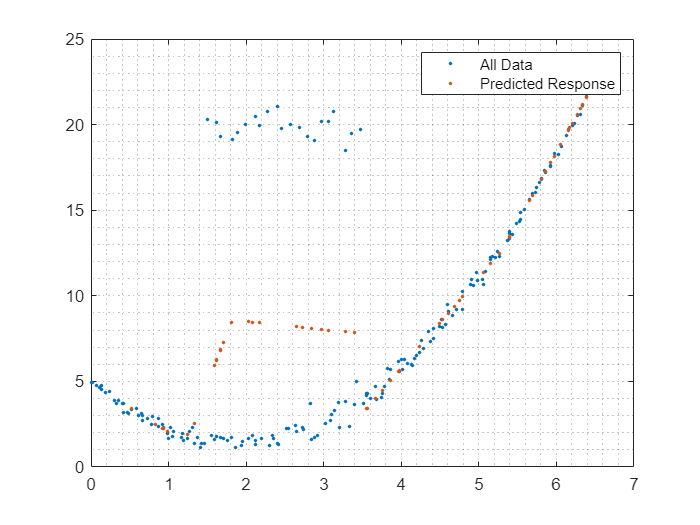

plot(data.x, data.y, ".")
hold on
plot(dataTest.x, yPred, ".")
grid minor
hold off
legend("All Data", "Predicted Response")